clear all

addpath (genpath('/home/johnpaustian/matlab/ClassifyImages'));

addpath (genpath('/home/johnpaustian/scratch/Imagery'));

dbFolder = '/home/johnpaustian/matlab/Sandbox/spv_datastore';

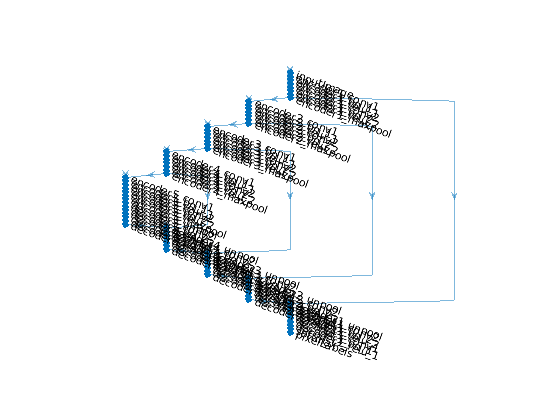

numClasses = 4;     %   update this when sulfides are added to labeled data

outputsize = [150 200];

%Set network image input size
imageSize = [outputsize 3];

%create lgraph object from SegNet layers (uninitalized encoder depth)
lgraph = segnetLayers(imageSize,numClasses,5);

%Replace classification layer with class weighted pixel classification

% lgraph = replaceLayer(lgraph,"pixelLabels",pxLayer); 

% Display segmentation network

plot( lgraph )

hAxes = gca; 
axis off

load spv_gTruth.mat

imds = imageDatastore( dbFolder,'FileExtensions','.tif' );

pxds = pixelLabelDatastore( spv_gTruth );

pximds = pixelLabelImageDatastore( imds,pxds,'OutputSize',outputsize,...
    'OutputSizeMode','resize' );

options = trainingOptions( 'sgdm', ...
    'ExecutionEnvironment','gpu',...
    'LearnRateSchedule','none', ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.3, ...
    'L2Regularization', 0.001, ...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',20, ...  
    'MiniBatchSize',8, ...
    'Shuffle','never', ...
    'CheckpointPath', tempdir, ...
    'VerboseFrequency',5,...
    'Plots','none' );

## Train Network

% Train neural network using pixel image datastore and pre-defined architecture

spv_lavanet = trainNetwork( pximds,lgraph,options );

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       20.89% |       1.3863 |          0.0010 |
|       5 |           5 |       00:00:04 |       20.89% |       1.3863 |          0.0010 |
|      10 |          10 |       00:00:07 |       20.89% |       1.3863 |          0.0010 |
|      15 |          15 |       00:00:09 |       20.89% |       1.3863 |          0.0010 |
|      20 |          20 |       00:00:11 |       20.89% |       1.3863 |          0.0010 |
|========================================================================================|



save( 'spv_lavanet.mat', 'spv_lavanet' )